# Q1. Transfer Learning - Image Classification *(50 points)*

## 1. Pretrained network (3)

###     1.1. Import AlexNet (1)

net = alexnet

net =   SeriesNetwork - 속성 있음:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


###     1.2. What is the input image size of AlexNet? (2)

      Enter your code to ouput the input image size of AlexNet.

layer=net.Layers

layer =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'     영상 입력         227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'    컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'    ReLU             ReLU
     4   'norm1'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'    그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'    ReLU             ReLU
     8   'norm2'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'    컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'    ReLU             ReLU
    12   'conv4'    그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'    ReLU             ReLU
    14   'conv5'    그

layer_input = layer(1)

layer_input =   ImageInputLayer - 속성 있음:

                      Name: 'data'
                 InputSize: [227 227 3]

   하이퍼파라미터
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [227×227×3 single]


input_sz = layer_input.InputSize

input_sz =    227   227     3


## 2. Importing dataset (7)

###     2.1. Create an image datastore (5)

      Create an image datastore which references the folder of the dataset.

imageDS = imageDatastore("raw-img_shrinked","IncludeSubfolders",true,"LabelSource","foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' ...\e030b20928e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' ...\e030b20929e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' ...\e030b2092be90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg'
                               ... and 1997 more
                              }
                     Folders: {
                              'C:\Users\hi\Documents\MATLAB\인공지능\week9 - mid\raw-img_shrinked'
                              }
                      Labels: [butterfly; butterfly; butterfly ... and 1997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
         

###     2.2 What ouput classes does the dataset contain? (2)

      Enter your code to output the classes of the dataset.

imageDS.Labels

ans = 2000×1 categorical 배열
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 


categories(imageDS.Labels)

ans = 10×1 cell 배열
    {'butterfly'}
    {'cat'      }
    {'chicken'  }
    {'cow'      }
    {'dog'      }
    {'elephant' }
    {'horse'    }
    {'sheep'    }
    {'spider'   }
    {'squirrel' }


*           View a sample image of each class*

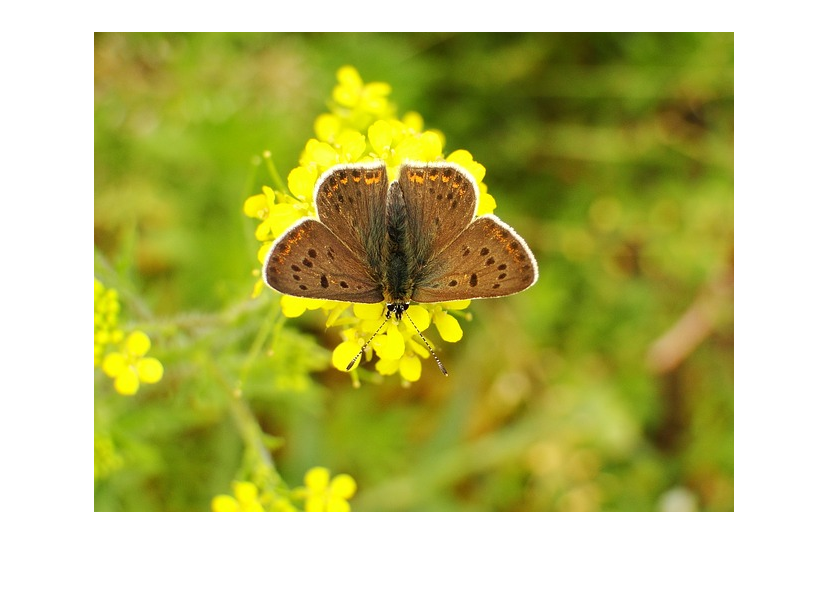

    %-------------- DO NOT modify this code--------------
    selectedClass="butterfly";
    classIdx = contains(imageDS.Files,selectedClass);
    countClass = sum(classIdx);
    randNum = randi([1,countClass],1);
    classRowNum = find(classIdx);
    classRandIm = readimage(imageDS, classRowNum(1)+randNum-1);
    imshow(classRandIm)

    %----------------------------------------------------

## 3. Preparing Data (10)

###     3.1. Split dataset (5)

      Split the dataset into train(0.8) and test data(0.2). **DO NOT include validation data.**

[trainImg, testImg]=splitEachLabel(imageDS,0.8)

trainImg =   ImageDatastore - 속성 있음:

                       Files: {
                              ' ...\e030b20928e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' ...\e030b20929e90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg';
                              ' ...\e030b2092be90021d85a5854ee454296eb70e3c818b413449df6c87ca3ed_640.jpg'
                               ... and 1597 more
                              }
                     Folders: {
                              'C:\Users\hi\Documents\MATLAB\인공지능\week9 - mid\raw-img_shrinked'
                              }
                      Labels: [butterfly; butterfly; butterfly ... and 1597 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
        

testImg =   ImageDatastore - 속성 있음:

                       Files: {
                              ' ...36b30e20fc063ed1584d05fb1d4e9fe777ead218ac104497f5c97faee8b1b8_640.jpg';
                              ' ...36b30e2bf2083ed1584d05fb1d4e9fe777ead218ac104497f5c97faee8b1b8_640.jpg';
                              ' ...36b30e2ef6053ed1584d05fb1d4e9fe777ead218ac104497f5c97faee8b1b8_640.jpg'
                               ... and 397 more
                              }
                     Folders: {
                              'C:\Users\hi\Documents\MATLAB\인공지능\week9 - mid\raw-img_shrinked'
                              }
                      Labels: [butterfly; butterfly; butterfly ... and 397 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
        

###     3.2. Augment data (5)

      Augment the data for transfer learning.

trainData = augmentedImageDatastore([227 227],trainImg,"ColorPreprocessing","gray2rgb")

trainData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 1600
                       Files: {1600×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


testData = augmentedImageDatastore([227 227],testImg,"ColorPreprocessing","gray2rgb")

testData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 400
                       Files: {400×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## 4. Modifying Network (5)

Modify appropriate layers of AlexNet so that the network works for your dataset.

layer(23)=fullyConnectedLayer(10);
layer(end)=classificationLayer()

layer =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'    영상 입력         227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'   컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'   ReLU             ReLU
     4   'norm1'   교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'   최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'   그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'   ReLU             ReLU
     8   'norm2'   교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'   최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'   컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'   ReLU             ReLU
    12   'conv4'   그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'   ReLU             ReLU
    14   'conv5'   그룹화된 컨벌루션   2 g

## 5. Training Network (10)

Create appropriate training options to obtain good prediction accuracy for the test data.

###     5.1. Create training options (5)

      The training options you **SHOULD KEEP** are as follows. The rest of training options are tunerable.

- Max Epochs: 10

- Display training progress

opts = trainingOptions("sgdm","MaxEpochs",10,"MiniBatchSize",50,"InitialLearnRate",0.0001,"Plots","training-progress")

opts =   TrainingOptionsSGDM - 속성 있음:

                    Momentum: 0.9000
            InitialLearnRate: 1.0000e-04
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 10
               MiniBatchSize: 50
                     Verbose: 1
            VerboseFrequency: 50
              ValidationData: []
         ValidationFrequency: 50
          ValidationPatience: Inf
                     Shuffle: 'once'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'training-progress'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddingDirection: 'right'
        Dispa

###     5.2. Train Network (5)

      Train network. You might see a sytax error when starting the training, and be required to add an optional argument in 3.2.

landnet = trainNetwork(trainData,layer,opts)

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：１０　｜　　　　　　１０．００％　｜　　　　　４．８６６７　｜　１．００００ｅ－０４　｜


｜　　　　　　　２　｜　　　　　　５０　｜　　　　　００：０４：１０　｜　　　　　　６０．００％　｜　　　　　１．２０６０　｜　１．００００ｅ－０４　｜


｜　　　　　　　４　｜　　　　　１００　｜　　　　　００：０７：３９　｜　　　　　　８２．００％　｜　　　　　０．４９８６　｜　１．００００ｅ－０４　｜


｜　　　　　　　５　｜　　　　　１５０　｜　　　　　００：１１：０８　｜　　　　　　７４．００％　｜　　　　　０．５８１２　｜　１．００００ｅ－０４　｜


｜　　　　　　　７　｜　　　　　２００　｜　　　　　００：１４：４６　｜　　　　　　９２．００％　｜　　　　　０．２６３９　｜　１．００００ｅ－０４　｜


｜　　　　　　　８　｜　　　　　２５０　｜　　　　　００：１８：３１　｜　　　　　　９２．００％　｜　　　　　０．１８７８　｜　１．００００ｅ－０４　｜


｜　　　　　　１０　｜　　　　　３００　｜　　　　　００：２２：３０　｜　　　　　　９２．００％　｜　　　　　０．１５２６　｜　１．００００ｅ－０４　｜


｜　　　　　　１０　｜　　　　　３２０　｜　　　　　００：２４：１５　｜　　　　　　９４．００％　｜　　　　　０．１５４９　｜　１．００００ｅ－０４　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


landnet =   SeriesNetwork - 속성 있음:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


## 6. Evaluating network (15)

Evaluate the network by classifying the test data, calculating the classification accuracy and displaying a confusion chart.

###     6.1. Predict the class of the test data (3)

testPred = classify(landnet, testData)

testPred = 400×1 categorical 배열
     dog 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     spider 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     squirrel 
     butterfly 
     butterfly 
     butterfly 
     squirrel 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 
     butterfly 


###     6.2. Calculate the prediction accuracy (10)

- Accuracy > 0.90             : 10 points

- 0.86 < Accuracy < 0.90  : 8 points

- Accuracy < 0.86             : 5 points

testGT = testImg.Labels;
testAcc = nnz(testPred==testGT)/numel(testPred)

testAcc = 0.8775

###     6.3. Display a confusion chart (2)

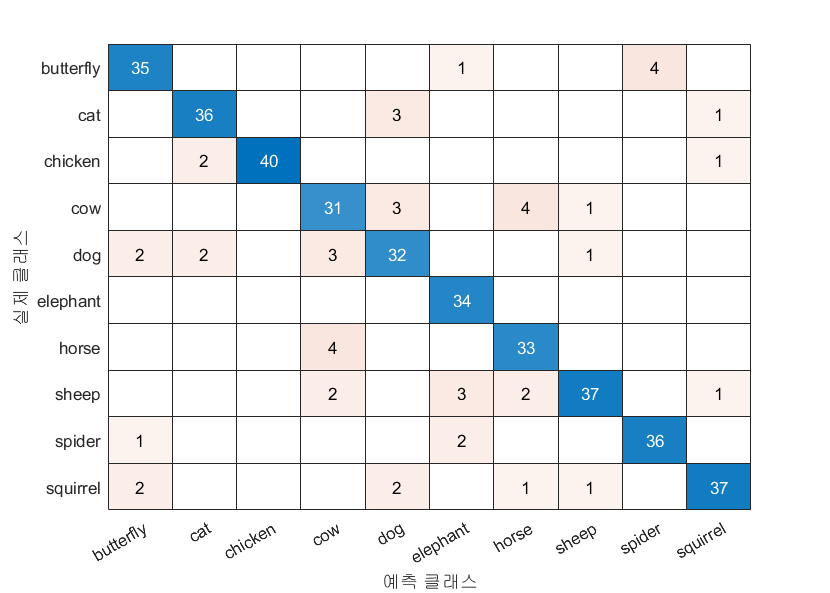

confusionchart(testPred,testGT)